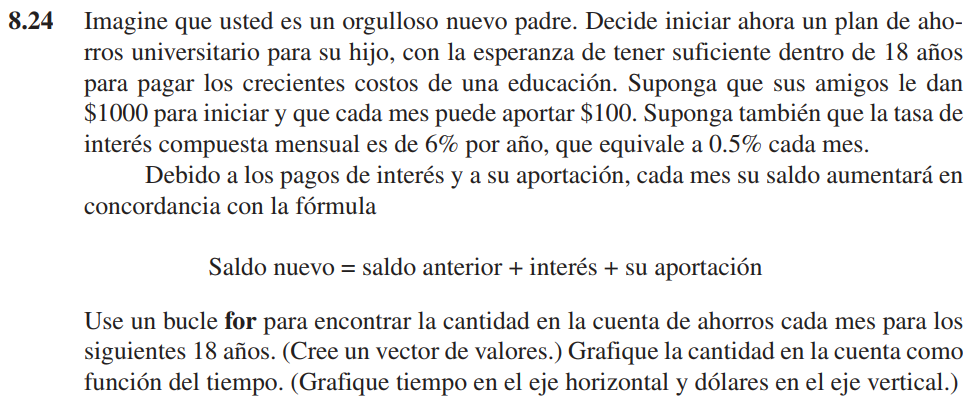

Los siguientes 3 problemas (24, 25 y 26) son consecutivos así que para revisar el resultado de cualquier enunciado se debe correr el código de cada uno desde el principio.

clear

initialMoney = 1000;
monthlyMoney = 100;
annualInterestRate = .06;
monthlyInterestRate = annualInterestRate/12;
time = 1:18*12;
money = [initialMoney zeros(1,length(time)-1)];

for i = time
    if i == time(end)
        break
    end
    money(i+1) = money(i) + monthlyMoney + money(i)*monthlyInterestRate;
end

plot(time,money)
    title 'Plan de ahorro universitario'
    xlabel 'Tiempo, meses'
    ylabel 'Dinero, $'
    grid

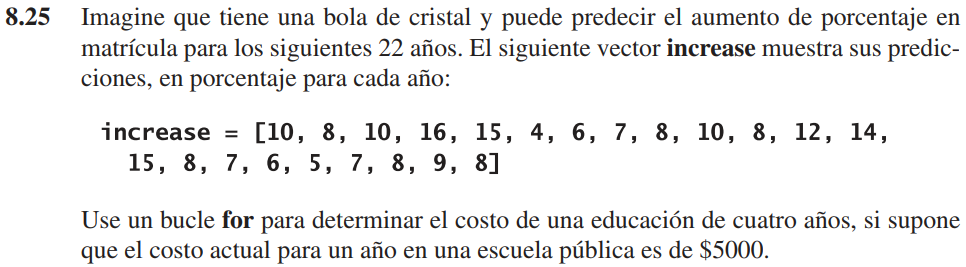

Considerar que el incremento de la matrícula es respecto a la del año anterior.

increase = [10 8 10 16 15 4 6 7 8 10 8 12 14 15 8 7 6 5 7 8 9 8];
currentCost = 5000;
totalCost = currentCost;

for i = 1:length(increase)
    if i == length(increase)
        break
    end
    totalCost(i+1) = totalCost(i) + totalCost(i)*(increase(i)/100);
end

sumCostIn18Years = sum(totalCost(1,18:end-1))   % Educación de 4 años.

if money(end) >= sumCostIn18Years
    fprintf(['El saldo ahorrado es $ %.2f y el saldo necesario es $%.2f,\n' ...
        'por lo tanto, los ahorros son suficientes.'],money(end),sumCostIn18Years)
else
    fprintf(['El saldo ahorrado es $ %.2f y el saldo necesario es $%.2f,\n' ...
        'por lo tanto, los ahorros no son suficientes.'],money(end),sumCostIn18Years)
end

El saldo ahorrado es $ 41365.26 y el saldo necesario es $104084.97,
por lo tanto, los ahorros no son suficientes.